%ecuaciones_de_estado_completo_x;
A= [            0  -0.00081454    -0.035336            0;
            0    -0.086973      -1.0254            0;
       9.1371       9.1371      -10.278            0;
            0            0            0      -7.3235];
B = [      0.47619            0      -4.8609            0;
       13.819   -0.0016082      -141.06            0;
            0            0      -201.21            0;
            0            0            0       7.3235];
C = eye(4);
D = zeros(4);

Fun_trans = C*inv(s*eye(4)-A)*B+D;

H(s)=Fun_trans;

H2(s)=inv(vpa(H(s)));
syms s w 
Arreglo(w)=H(j*w).*(H2(j*w)');
vpa(Arreglo(w),3)

Arreglo(0);
vpa(Arreglo(0),2)

$$ans = \left(\begin{array}{cccc} 7.0 & 2.2e-3 & -6.0 & 0\\ 4.8e-3 & 1.0 & -2.6e-3 & 0\\ -6.0 & -3.8e-5 & 7.0 & 0\\ 0 & 0 & 0 & 1.0 \end{array}\right)$$

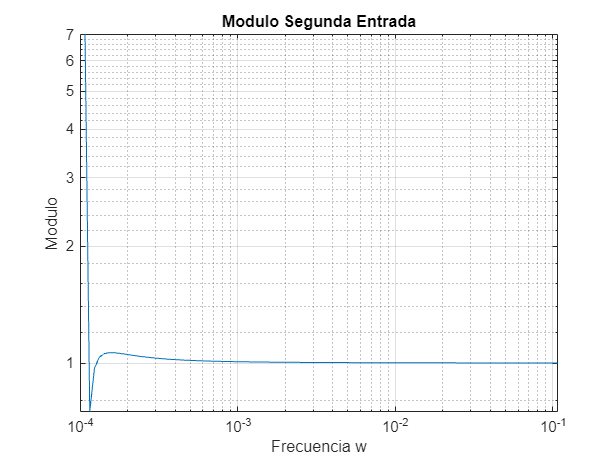

n_max = 100;
m_max = 101;
n = 0:n_max;
m = 1:m_max;
w_min = 10^(-4);
w_max = 10^(-1);

ratio = log10(w_max/w_min)*(1/n_max);

omega(m) = w_min*(10.^(m*ratio));

Arr = Arreglo(n);
Arr1 = vpa(abs(Arr{1,1}));
Arr2 = vpa(abs(Arr{2,2}));
loglog(omega(m),Arr1)
title('Modulo Segunda Entrada')
xlabel('Frecuencia w')
ylabel('Modulo')
grid on

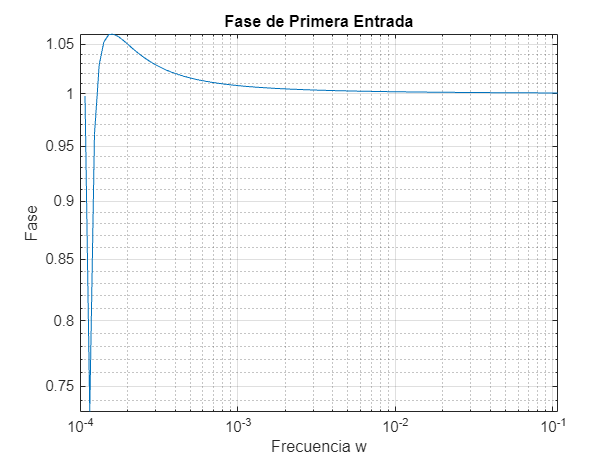

loglog(omega(m),Arr2)
title('Modulo de Primera Entrada')
grid on

title('Fase de Primera Entrada')
xlabel('Frecuencia w')
ylabel('Fase')
grid on